# MAIN CODE FILE

This code controls a wheeled autonomous rover performing a series of three outdoor missions around the Olin Oval. The missions are:

- Waypoint Navigation

- Docking

- Scientific Payload Delivery

This program will prompt the user for a mission number, enter the robot control loop and run the behaviour engine specific to that mission. To find its way around the oval, the rover travels along GPS location waypoints. To navigate around potential obstacles in an outdoor environment, the rover has a sensory suite that adds data to a global occupancy grid. From this grid, a weighted vector (brainwave) is produced that minimizes the potential for collision. Other mission-specific tasks use this concept of brainwave arbitration to determine which steering angle is the best to take.

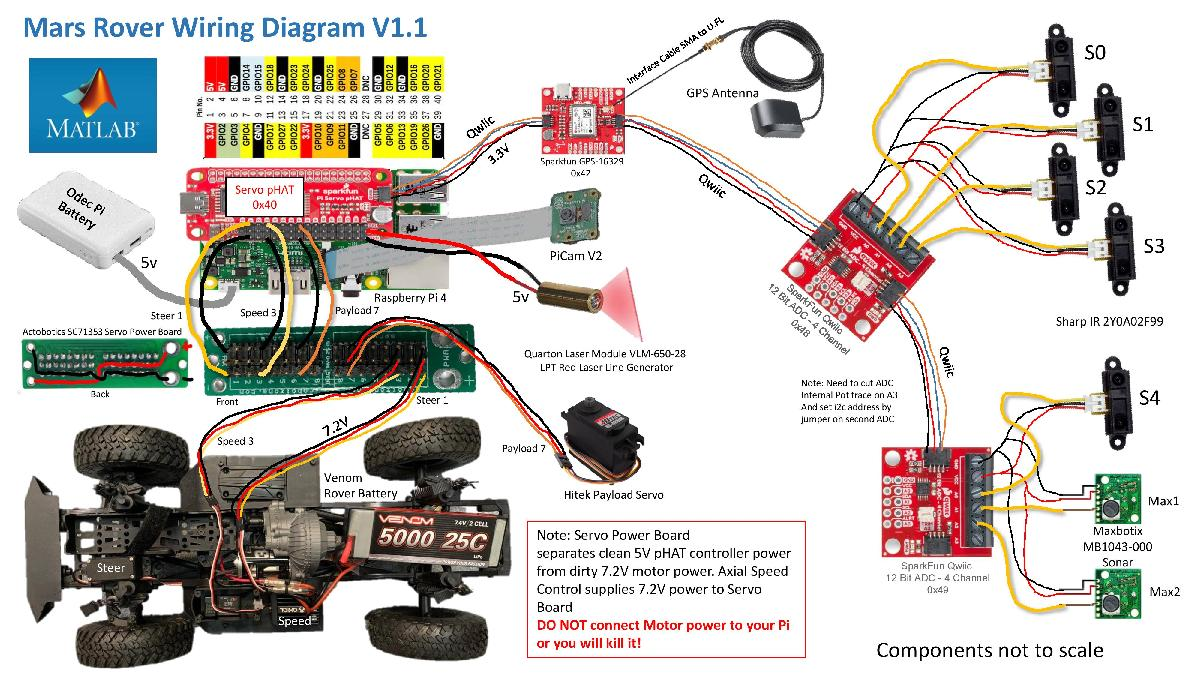

- Clear indication of what external Matlab code parts

The program OlinRoverSetup is used to set up the rover’s Raspberry Pi, sensing and actuation hardware, and create global variables. It's also where mission parameters and data, such as waypoints and the main occupancy grid, are set up.

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 
[robotPi, blinkLED]= RaspPiSetup()

% Turn on board LED on and off to signal program has started 
Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

% Set up servos, PiCam, and QWIIC analog input
[roverServos, roverJoy] = ServoSetup(robotPi)
[robotCam] = PiCamSetup(robotPi)
[rawRangeData] = QWIICInputSetup(robotPi)
[neo] = GPSSetup(robotPi)
[roverJoy] = JoystickSetup(1)

**INITIALIZE ROVER OCCUPANCY GRID**

% Create an empty map of the same dimensions as the test track map                      
roverOccupancyGrid = occupancyMap(100,100);  % Make empty map the same size
% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);         % Show the map in figure window

**Plotting Waypoints Onto Occupancy Grid**

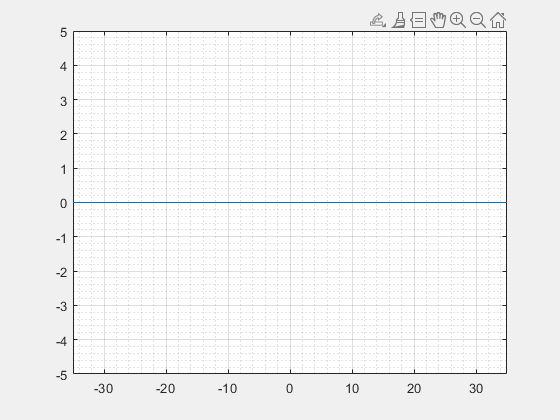

load waypoints.mat

p = 0.7;
for i = 1:length(waypoints)
    [gridIndex] = GPSCoordToGridIndex(waypoints(i,:),waypoints);
    updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],p);
end
% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
show(roverOccupancyGrid);

% Create free floating figure (Arbiter)
figureArbiter = figure('name', 'BrainWavesArbitor', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureArbiter);                            
    pbrain = plot([-35:35], zeros(71,1));
    axis([-35 35 -5 5]);
    grid on;
    grid minor;

**CREATE GLOBAL VARIABLES**

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero
GPSToGridRatio = 2; % CHANGE THIS
% Create a differential drive rover (takes speed and heading for inputs)
diffDriveRover = differentialDriveKinematics("VehicleInputs", "VehicleSpeedHeadingRate"); 

**CREATE MISSION DEFINITION FILE**

% Create index for MDF table
WayPoint = (0:1:4);                                        
WayPoint = WayPoint';

% Create inital target waypoints
xLongitude = [ -71.227875 ; -71.227875 ;-71.227875 ;-71.227875 ;-71.227875];
yLatitude = [ 42.276295 ; 42.276295 ;42.276295 ;42.276295 ;42.276295];

% Build list of desired behaviors for Mission 1
BehaviorOne = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
MDFOne = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build Mission Definition File (MDF) table
 
% Build list of desired behaviors for Mission 2
BehaviorTwo = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
MDFTwo = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build MDF table

% Build list of desired behaviors for Mission 2
BehaviorThree = ['Forward_____' ; 'purePursuit_'; 'purePursuit_'; 'pursuitAvoid' ; 'pursuitAvoid'];
MDFThree = table(WayPoint,xLongitude,yLatitude,Behavior)      % Build MDF table

**ASK FOR MISSION NUMBER**

mission_number = input('Enter mission number: ');

**READY TO RUN ROBOT?**

userInput = questdlg('Ready to run Rover?', 'Start Mission');

## Run Robot Control Loop

if (strcmp(userInput,'Yes'))
    comSteer = 50;                       % set steering center
    comSpeed = 50;                       % set drivespeed to zero
    controlFlag = 1;                     % create a loop control
end

% Some initial code to get out of the dock
waypoint = 1;
load('waypoints.mat');
switch mission_number
    case 1 % Mission 1: Driving at obstacle avoidance
        MDF = MDFOne;
    case 2 % mission 2: docking
        MDF = MDFTwo;
    case 3 % mission 3: payload
        MDF = MDFThree;
    while true
        % Get Current Location
        [roverOccupancyGrid, roverBearing, roverLocation, gate_number] = GPSGetLocation(roverOccupancyGrid,neo)
        % Pantilt and Sense
        [roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam)
        % Find target waypoint 
%             targetWaypoint = [MDF{waypoint,2} MDF{waypoint,3}];
        targetWaypoint = [waypoints(waypoint,1) waypoints(waypoint,2)];      % new waypoints
        % Find angle for the next waypoint and turning in that
        % direction
        bearing = GoToWayPoint(roverOccupancyGrid,targetWaypoint);
        DriveRover(robotPi,roverServos,bearing, 0);
        % Find behaviour to execute
        roverBehavior = MDF{WPn,4};
        % Find distance between rover and target waypoint
        distToTarget = norm(roverLocation-targetWaypoint);
        
        % If rover is not at the target gate, repeat WP loop
        while deg2km(distToTarget)/1000 > 5
            tic
            while toc < 3
                % Execute think behaviour( also think about what do to for cases
                % where there is more than one behaviour to execute)
                [steerRef] = ExecuteThinkBehaviour(roverBehavior);
                roverLocation = DriveRover(robotPi,roverServos,steerRef,61,roverLocation) % act on the given steering angle
            end
            roverLocation = DriveRover(robotPi,roverServos,steerRef,0,roverLocation)   % stop rover
            pause(1)
            % Update rover location and distance to target waypoint
            [roverOccupancyGrid, roverBearing] = GPSGetBearing(roverOccupancyGrid, neo)
            distToTarget = norm(roverLocation-targetWaypoint);   % update distance to target
        end
        waypoint = waypoint + 1;
        if waypoint == 7     % If rover has reached last waypoint
            break
        end
    end
end

## Clean shut down

Put all actualtors into a safe position, release all control objects and shut down all communication paths.

% Stop program and clean up the connection to Pi
% when no longer needed 
  roverServos.setServoPWM(1,50);       % Center steering Wheels
  roverServos.setServoPWM(3,50);       % Turn Drive Motor off
  % close all;                           % clear data figure plots
  clc                                  % clear commad window
  clear robotPi                        % clear Pi object
  beep              % play system sound to let user know program is ended
  

Check quasi real-time loop performance (Dave and Matlab working on ways to speed this up)

  disp(r);
  stats = statistics(r)                % check real-time loop execution time stats
  disp('Rover Test program has ended');
  disp('Dont forget to shut down Pi cleanly before you power it off');

*At end of each programming session, please don't forget to shutdown your Pi cleanly by using the follwing at the command line:*

## `h = robotPi`

## `h.execute('sudo shutdown -h now')`

  % leave next line commented out
  %  profile viewer                    % view code runtimes graphically

## Robot Functions(store the local functions here)

**SENSE FUNCTIONS**

function[roverOccupancyGrid, roverBearing, gate_number] = GPSGetBearing(roverOccupancyGrid,neo) % this will be provided from canvas
    basic_data = neo.getBasic();
    % roverLocation = [basic_data.longitude basic_data.lattitude];
    roverBearing = basic_data.heading;
    % add code for making the gate number thing work
    gate_number = 1;
    % plotting rover position on occupancy grid through conversion
    [gridIndex] = GPSCoordToGridIndex(GPSCoordinate);
    pvalues = 0.6; % this is the value for the rover position
    updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],pvalues);
end

% function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, roverBearing, roverLocation, adcDevice1, adcDevice2)

function [roverOccupancyGrid, obstaclePosX, obstaclePosY] =  SharpIRRange(roverOccupancyGrid,roverBearing, roverLocation, adcDevice1, adcDevice2)
    clf
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)]; 
     angles = [ -60+roverBearing -30+roverBearing 0+roverBearing 30+roverBearing 60+roverBearing]; % chagne this later     
     threshold = 40;
     %convert to lat/long
      threshold = threshold/1100000;
%      for i = 1:5
        % voltage to distance     
        distance = (rawRangeData - 2.805)./(-0.03316)
        distance = distance./11100000;
         %store pts
          pts = zeros(2,6);
          pts(1,6) = roverLocation(1);
          pts(2,6) = roverLocation(2);
        for i = 1:5
         if distance(i)< threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance(i), roverLocation)
            %plot in local reference frame
            pts(1,i) = obstaclePosX;
            pts(2,i) = obstaclePosY;
            
            [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY])
            updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
         end  
        end
         %plot in local reference frame
        figure
        plot(pts(1,1:5), pts(2,1:5),"x");
          title("IR Local Plot")
        hold on 
         plot(pts(1,6), pts(2,6),"ro");
        
     end  


function [roverOccupancyGrid] =  SharpSONARRange(roverOccupancyGrid,roverBearing, roverLocation, adcDevice1, adcDevice2)
    clf
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData1(3:4)]; 
     angles = [ -90+roverBearing  90+roverBearing]; % chagne this later     
     threshold = 100;% in cm
     %convert to lat/long
      threshold = threshold/1100000
%      for i = 1:5
        % voltage to distance     
        distance = (rawRangeData - 0.01063)./(0.01584)
        distance = distance./11100000
         %store pts
          pts = zeros(2,3);
          pts(1,3) = roverLocation(1);
          pts(2,3) = roverLocation(2);
        for i = 1:2
         if distance(i)< threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance(i), roverLocation)
            %plot in local reference frame
            pts(1,i) = obstaclePosX;
            pts(2,i) = obstaclePosY;
            
            [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY])
            updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
         end  
        end
         %plot in local reference frame
        figure
        plot(pts(1,1:2), pts(2,1:2),"x");
        title("SONAR Local Plot")
        hold on 
         plot(pts(1,3), pts(2,3),"ro");
     end  


function[roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
% Mark obstacles on the grid
end

function[roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, roverBearing, roverLocation, robotCam) % color masking for obstacles
% Mark obstacles on the grid
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (rawRangeData(1, 1)-0.01063)/0.01584; 
    distanceRight = (rawRangeData(2, 1)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation);
        [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY]);
        updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation);
        [gridIndex] = GPSCoordToGridIndex([obstaclePosX obstaclePosY]);
        updateOccupancy(roverOccupancyGrid, [gridIndex(1) gridIndex(2)], 0.1);
    end
end

function[roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, panAngle, tiltAngle) 
% Find the location of the red dot, and mark it on the grid
end

function[roverOccupancyGrid]  =  PiCamAprilTagFind(roverOccupancyGrid,panAngle, tiltAngle) %why is there pan and tilt angle
% Find the location of the april tags and mark it on the grid
end

function[roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
        [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
        [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end

function[roverOccupancyGrid] = MissionTwoSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation)
    joystickControl=1
    while joystickControl == 1
        gtest=input('Ready to sense? type Y then hit enter','s');
        [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
        DrivePanTilt(panAngle, tiltAngle)
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % fill in other variable
        [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % laser for obstacle avoidance
        [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation) % fill in other variables
        [roverOccupancyGrid]  =  PiCamAprilTagFind(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % look for dock april tag
        [roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation) % look for dock red dot
        
        figure(figureRoverOccupancy);
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
            
        joystickControl=input('Keep controlling joystick? (0-1)');
    end
end

function[roverOccupancyGrid] = MissionThreeSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation)

end

function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**

function [posX, posY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
        omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        posX = roverLocation(1) + (distance*cosd(modulo))
        posY = roverLocation(2) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        posX = roverLocation(1) + (distance*cosd(modulo))
        posY = roverLocation(2) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        posX = roverLocation(1) - (distance*cosd(modulo))
        posY = roverLocation(2) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        posX = roverLocation(1) - (distance*cosd(modulo))
        posY = roverLocation(2) + (distance*sind(modulo))
    end
end
    
function [waypointSteeringVector] = GoToWayPoint(roverOccupancyGrid,targetWaypoint, roverBearing, roverLocation)

    % Initialize the waypoint vector
    waypointSteeringVector = zeros(13,1);
    
    % Do math to find radius of bumblebee circle
    xdist = targetWaypoint(1) - roverLocation(1);
    ydist = targetWaypoint(2) - roverLocation(2);
    omega = 360 - roverBearing;
    a = 1-cosd(omega)^2-sind(omega)^2;
    b = 2*(cosd(omega)*xdist + sind(omega)*ydist);
    c = xdist^2 + ydist^2;
    radius = roots(a, b, c);
    
    % Convert radius to a bearing
    n = 1 % steering ratio
    s =  1;% wheel base
    a = (n/2)*acos((2-(s^2/radius^2))/2); % steering angle
    
    
    % finding the index for the turn angles to change
    a = (round(a/30))*30;
    turnAngles = -180:30:180;   % 13 vectors( y range is from -1 to 1)
    ind = find(abs(turnAngles - bearing) <= 0.001);
    
    % Change the steering vector
    waypointSteeringVector(ind) = 0.5;

end

function [avoidSteeringVector] = ObstacleAvoid(roverOccupancyGrid, roverLocation)
turnAngles = -180:30:180;   % 13 vectors( y range is from -1 to 1)
mapMatrix = occupancyMatrix(roverOccupancyGrid);
avoidSteeringVector = zeros(71,1);
threshold_distance = 10; % change this value
% if the obstacles are marked as 0.1, find the index of the points marked
[location(:,1),location(:,2)] = find(abs(mapMatrix - 0.1) <= 0.001);
for i = 1:length(location(1))
    % this should be the coordinates of a single wall point
    obstacle_point = [location(i,1), location(i,2)];
    % finding the distance between the rover and the obstacle
    dist = norm(roverLocation - obstacle_point);
    % if the distance is less than the threshold distance
    % then find the bearing of that obstacle point
    if dist <= threshold_distance
        xdist = roverLocation(1) - obstacle_point(1);
        ydist = roverLocation(2) - obstacle_point(2);
        bearing = atan(xdist/ydist);        
    end
    % to round by the nearest 30
    bearing = (round(bearing))
    % finding the index for the turn angles to change
    ind = find(abs(turnAngles - bearing) <= 0.001);
    % changing the avoid vector
    avoidSteeringVector(ind) = -1;
end
end

function [bumbleBeeSteeringVector] = WallAvoid(roverOccupancyGrid, direction)
% Create a steering brainwave based on the location of the walls around the
% rover
% I think we don't need this anymore?
end

function [bumbleBeeSteeringVector] = RedDotDockRover(roverOccupancyGrid)
% Create a steering brainwave based on the coordinates of the red dot above
% the dock
end

function [bumbleBeeSteeringVector] = AprilTagDockRover(roverOccupancyGrid)
% Create a steering brainwave based on the information found from the
% apriltag on the dock
end

function [tag] = CheckAprilTag(roverOccupancyGrid)
% Check to see if the April Tag is ours or not and output yes or no
% Get code from Amy
end


function [steeringAngle] = roverArbiter(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivoursav, output a final direction
    
    % If parameters are not given, default as vector of zeros
    num_angles = 71;
    num_behaviors = 5;
    switch nargin
        case 4
            behavior5 = zeros(1,num_angles);
            num_behaviors = 4;
        case 3
            behavior4 = zeros(1,num_angles);
            behavior5 = zeros(1,num_angles);
            num_behaviors = 3;
        case 2
            behavior5 = zeros(1,num_angles);
            behavior4 = zeros(1,num_angles);
            behavior3 = zeros(1,num_angles);
            num_behaviors = 2;
        case 1
            behavior5 = zeros(1,num_angles);
            behavior4 = zeros(1,num_angles);
            behavior3 = zeros(1,num_angles);
            behavior2 = zeros(1,num_angles);
            num_behaviors = 1;
    end    
    steeringVector = (behavior1 + behavior2 + behavior3 + behavior4 + behavior5)/num_behaviors;
    
    turnAngles = -35:35;
    
    figure(figureArbiter)                 % go to brain waves figure
    %clf                               % clear figure of old waves
    plot(turnAngles, behavior1, "b-+");        % plot behaviour 1 waveform
     ax=gca;
     ax.XDir = 'reverse';
    axis([-8 8 -8 8]);
    grid on;
    grid minor;
    hold on
    plot(turnAngles, behavior2, "g-+");
    plot(turnAngles, behavior3, "c-o");
    plot(turnAngles, behavior4, "y-o");
    plot(turnAngles, behavior5, "b-o");
    
    plot(turnAngles, steeringVector, "r-+");       % plot sum of steer angle waveform
    legend('behavior1','behavior2','behavior3','behavior4','behavior5') % label plot
    hold off
    
    [x,ind] = max(steeringVector);
    steeringAngle = turnAngles(ind);
    
end

function [steerRef] = ExecuteThinkBehaviour(roverBehavior, missionNumber)
   switch roverBehavior
       case 'Forward_____'
           % -180 -150 -120 -90 -60 -30 0 30 60 90 120 150 180
           goStraightVector = [0 0 0 0 0 0 1 0 0 0 0 0 0];
           steeringVector = roverArbiter(goStraightVector)
       case 'purePursuit_' % pure pursuit to next waypoint
           wallSteeringVector = wallAvoid();
           steeringVector = roverArbiter(wallSteeringVector)
       case 'pursuitAvoid' % pure pursuit to next waypoint, while avoiding obstacles
           wallSteeringVector = wallAvoid();
           avoidSteeringVector = WbstacleAvoid();
           steeringVector = roverArbiter(wallSteeringVector, avoidSteeringVector)
       % DEFINE MORE CASES
   end
    [steerMaxValue, steerMaxIndex] = max(steeringVector);  % find peak of summed waveform
    steerRef = steeringVector(steerMaxIndex);              % return peak -> most promising steering angle
end

function [gridIndex] = GPSCoordToGridIndex(GPSCoordinate)
    bottom_left_corner = [42.293000, -71.264461];
    xgrid = (GPSCoordinate(1) - bottom_left_corner(1))/(10^(-5)); % plot it on to 100 by 100
    ygrid = (GPSCoordinate(2) - bottom_left_corner(2))/(10^(-5));
    gridIndex = [xgrid ygrid];  
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DeployPayload(payloadNumber)
    % TODO
end

function [roverLocation] = DriveRover(robotPi,roverServos,direction,speed,roverLocation)
    roverServos.setServoPWM(1,direction);    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

### **ROVER SETUP FUNCTIONS**

**SETUP PI**

function [robotPi, blinkLED] = RaspPiSetup()
% RaspPiSetup creates and configures a Raspberry Pi to be a simple robot 
% controller. It requires no inputs and returns a rasPi object

% Create a *raspi* object.
%    robotPi = raspi('192.168.16.65', 'pi', 'raspberry');   % lab pi
   robotPi = raspi('192.168.35.1', 'pi', 'raspberry');   % melody pi
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
   blinkLED = robotPi.AvailableLEDs{1};
end

**SETUP SERVOS**

function [roverServos, roverJoy] = ServoSetup(robotPi)
% Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 
scanI2CBus(robotPi)

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(robotPi);
pSteer = 1;                                   % set Steer servo to pin 1
pSpeed = 3;                                   % set Speed servo to pin 3
comSteer = 50;                                % set intial steer command to 0 angle
comSpeed = 50;                                % set intial speed command to 0 speed
roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero

% Define joystick ID (if only using 1 joystick, this will likely be '1')
ID = 1;

% Create joystick variable
roverJoy=vrjoystick(ID);

% Visualize the test servo commands in robot coordinate system.
% create a new free-standing figure to display the servo data, rover
% at center
localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
PlotServoSettings(localServoPlot,comSteer,comSpeed)
end

**SETUP PICAM**

function [robotCam] = PiCamSetup(robotPi)
% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorithms crazy by constantly changing
SetUpPiCamera(robotCam);
end

**SETUP QWIIC ANALOG INPUT**

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors

rawRangeData1 = SENSE_ADC(adcDevice1)
rawRangeData2 = SENSE_ADC(adcDevice2)
rawRangeData = [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
PlotSensorData(localSensorPlot, rawRangeData);
end



**SETUP GPS**

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end

**ROBOT FUNCTIONS**

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end